clear;

Nvar = 2;
Nmax = 50;
errodf = 15e-3;
NPontosIniciais = 7;
x_values=[-11;-11]; y_values=[7;7];

PontosIniciais = getNPontosIniciais(NPontosIniciais, Nvar, x_values, y_values);
g = @(x) x(1)*(x(1) + 3)*(x(1) - 3)*(x(1) - 5) + x(2)*(x(2) + 3)*(x(2) - 3)*(x(2) - 5);
lambda = 0.0005;

## Teste 1

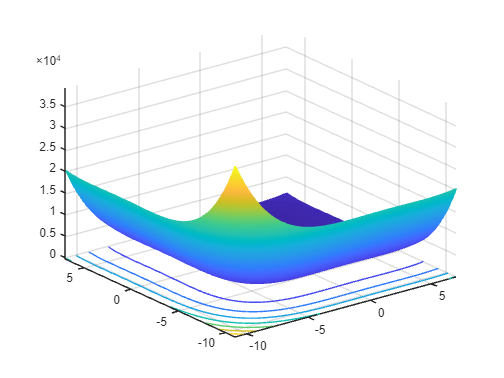

tic;
[Lista, LNit, Lopt] = steepest_descent_static(g, Nmax, errodf, PontosIniciais, x_values, y_values, lambda);
tempo_execucao_teste1 = toc;
close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

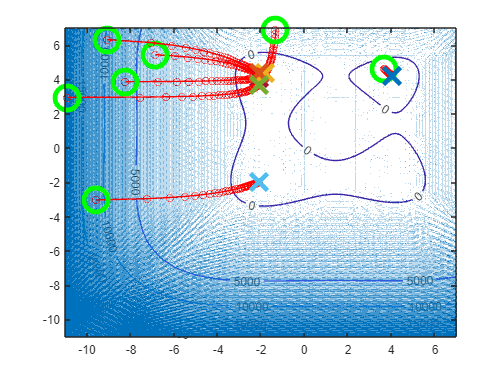


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 2

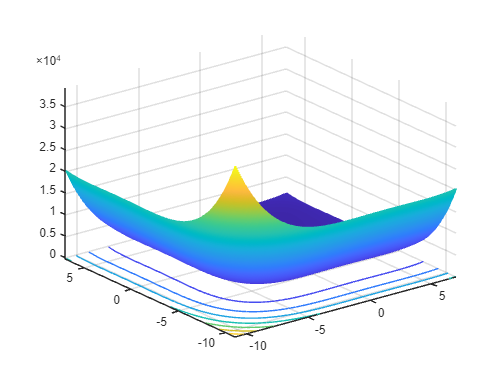

tic;
[Lista, LNit, Lopt] = steepest_descent_wolfe(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste2 = toc;
close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

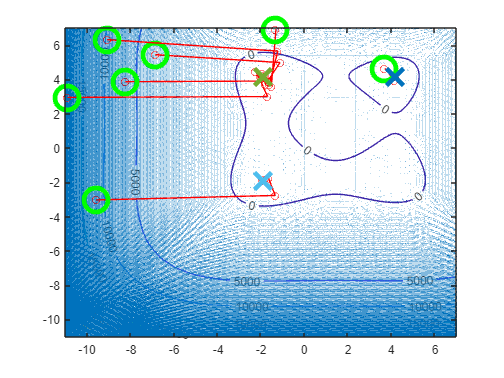


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off

## Teste 3

tic;
[Lista, LNit, Lopt] = newton_raphson(g, Nmax, errodf, PontosIniciais, x_values, y_values);
tempo_execucao_teste3 = toc;
close all

nivelGraficos(g,x_values(1),y_values(1),x_values(2),y_values(2))

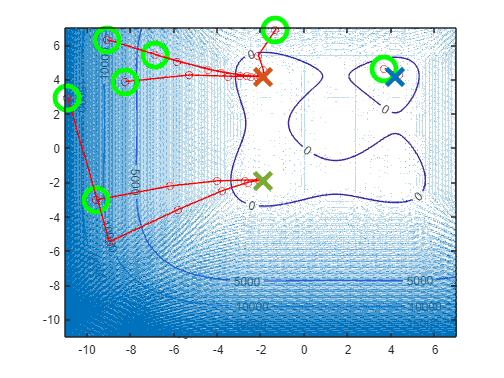


hold on

graficosLineSearch(Lista,LNit,Lopt)

hold off